Лабораторная работа №2

Управление для плоского робота открытой кинематики

Топольницкий А.

Вариант №53

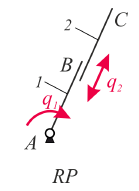

Рисунок 1.

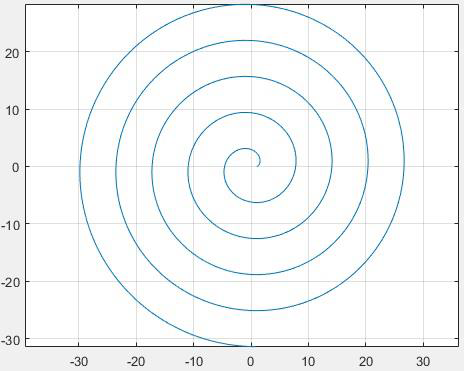

Рисунок 2.

Исходные данные:

- Задана конфигурация робота, изображённая на Рисунке 1. Первое звено вращательное, второе призматическое, то есть схема RP

- Необходимо реализовать траекторию, изображённую на рисунке 2.

- Параметры звеньев следующие: $L1 = 0.56  \; m, \; M1 = 0.72 \; kg, \; L2 =0.59  \; m , \; M2 = 0.57  \; kg$

Задание:

- Реализовать управление плоским роботом по положению с помощью ПИД регулятора (без построения модели робота);

- Реализовать управление плоским роботом по положению на основе динамической модели;

- Реализовать управление плоским роботом по импедансу с компенсацией гравитации

- Сравнить поведение и производительность робота при разных способах управления

Ход работы:

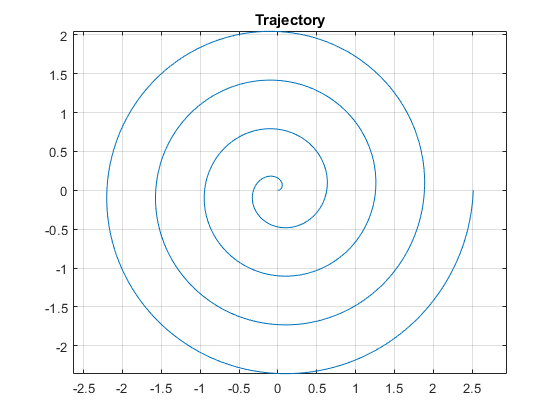

clc

k=0.1;
theta=linspace(0,8*pi,1000);
r=k*theta;
x=r.*cos(theta);
y=r.*sin(theta);
plot(x,y)
axis equal
grid on
title('Trajectory')

L1 = 0.56; %Length 1 link m
L2 = 0.59; %Length 2 link m
AB = [L1 0.1 0.1]; %scales 1st link
BC = [L2 0.05 0.05]; %scales 2d link
m1 = 0.72; %Mass 1 kg
m2 = 0.57; %Mass 2 kg
a = 0.06;
Base = [0.2*L1 0.2*L1 0.2*L1]; %Base parametrs

%Controller coefficients
kp = 900;
ki = 350;
kd = 300;

kp2 = 700;
ki2 = 300;
kd2 = 300;


figure;
plot(out.position.q1_act.time, out.position.q1_act.Data)

Dot indexing is not supported for variables of this type.

hold on
grid minor
title('Изменение q_1')
plot(out.position.q1_des.time, out.position.q1_des.Data)
legend('q_{1_{act}}', 'q_{1_{des}}')
xlabel('t [s]');
ylabel('q [rad]');

figure;
plot(out.position.q2_act.time, out.position.q2_act.Data)
hold on
grid minor
title('Изменение q_2')
plot(out.position.q2_des.time, out.position.q2_des.Data)
legend('q_{2_{act}}', 'q_{2_{des}}')
xlabel('t [s]');
ylabel('q [m]');
figure;
plot(out.tau.tau1.time,out.tau.tau1.Data)
hold on
plot(out.tau.tau2.time,out.tau.tau2.Data)
grid minor;
title('Изменение моментов')
legend('\tau_1', '\tau_2');
xlabel('t [s]');
ylabel('\tau [Nm]');
ylim([-30 30]);

figure;
plot(out.position.x_act.Data, out.position.y_act.Data)
grid minor
hold on
plot(out.position.x_des.Data, out.position.y_des.Data)
title('Сравнение траекторий')
legend('p_{act}','p_{des}')

Вывод:

В первой части лабораторной производилась реализация управления роботом по положению с помощью ПИД регулятора. После настройки ПИДа по графикам видно, что желаемое и реальное изменение обобщённых координат практически совпало. При построении графика моментов и траектории видны скачки в начальные момементы времени - резкий переход положения работа из заданного начального в необходимое